# Questão 4

## Para os dados 1

clear;
fileID = fopen('dados_1.txt', 'r');
formatSpec = '%f %f';
sizeData = [2 Inf];
dados_1 = fscanf(fileID, formatSpec, sizeData);
dados_1 = transpose(dados_1);

Estimação usando modelo ARX

y_1 = dados_1(:, 1);
u_1 = dados_1(:, 2);

% Modelo ARX de ordem 1
[theta1, estimative1] = LS(1, y_1, u_1);
error1 = y_1 - estimative1;
% Modelo ARX de ordem 2
[theta2, estimative2] = LS(2, y_1, u_1);
error2 = y_1 - estimative2;
% Modelo ARX de ordem 3
[theta3, estimative3] = LS(3, y_1, u_1);
error3 = y_1 - estimative3;
% Modelo ARX de ordem 4
[theta4, estimative4] = LS(4, y_1, u_1);
error4 = y_1 - estimative4;
% Modelo ARX de ordem 5
[theta5, estimative5] = LS(5, y_1, u_1);
error5 = y_1 - estimative5;

Estimação com modelo ARMAX

% Modelo ARMAX de ordem 1
[theta1x, estimative1x] = LS(1, y_1, u_1, error1);
error1x = y_1 - estimative1x;
% Modelo ARMAX de ordem 2
[theta2x, estimative2x] = LS(2, y_1, u_1, error2);
error2x = y_1 - estimative2x;
% Modelo ARMAX de ordem 3
[theta3x, estimative3x] = LS(3, y_1, u_1, error3);
error3x = y_1 - estimative3x;
% Modelo ARMAX de ordem 4
[theta4x, estimative4x] = LS(4, y_1, u_1, error4);
error4x = y_1 - estimative4x;
% Modelo ARMAX de ordem 5
[theta5x, estimative5x] = LS(5, y_1, u_1, error5);
error5x = y_1 - estimative5x;

Calculando erros de validação:

epsilon = length(y_1)/2;

% Validação Modelo 1
[estimative1v, error1v] = validate(theta1, epsilon, y_1, u_1);
% Validação Modelo 2
[estimative2v, error2v] = validate(theta2, epsilon, y_1, u_1);
% Validação Modelo 3
[estimative3v, error3v] = validate(theta3, epsilon, y_1, u_1);
% Validação Modelo 4
[estimative4v, error4v] = validate(theta4, epsilon, y_1, u_1);
% Validação Modelo 5
[estimative5v, error5v] = validate(theta5, epsilon, y_1, u_1);

Comparativo dos erros de estimação e validação usando erro médio quadrático:

error = [mean(error1.^2), mean(error1v.^2), mean(error1x.^2)];
error = [error; mean(error2.^2), mean(error2v.^2), mean(error2x.^2)];
error = [error; mean(error3.^2), mean(error3v.^2), mean(error3x.^2)];
error = [error; mean(error4.^2), mean(error4v.^2), mean(error4x.^2)];
error = [error; mean(error5.^2), mean(error5v.^2), mean(error5x.^2)];
error

error =     0.0126    0.0157    0.0110
    0.0110    0.0121    0.0094
    0.0094    0.0110    0.0092
    0.0093    0.0110    0.0088
    0.0091    0.0109    0.0087


Como o erro de validação a partir do modelo de ordem 3 não apresenta tanta variação, pode-se concluir que o melhor modelo para o sistema em questão é o modelo de ordem 3.

disp(theta3x);

   -0.0387
    0.4938
    0.2591
    0.1136
    0.0874
    0.0264
    0.3964
   -0.3421
   -0.0117



Gráfico da estimativa escolhida

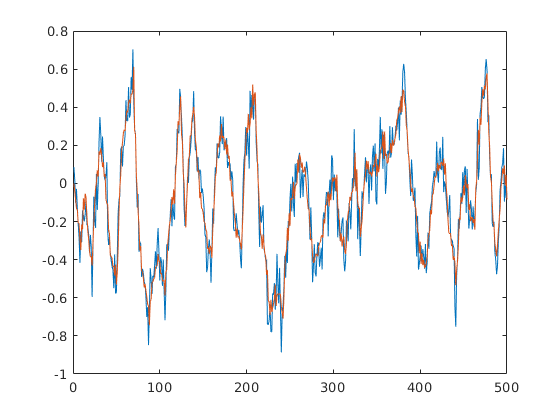

plot(y_1);
hold on;
plot(estimative3x);
hold off;

## Para os dados 2

clear;
fileID = fopen('dados_2.txt', 'r');
formatSpec = '%f %f';
sizeData = [2 Inf];
dados_2 = fscanf(fileID, formatSpec, sizeData);
dados_2 = transpose(dados_2);

Estimação usando modelo ARX

y_2 = dados_2(:, 1);
u_2 = dados_2(:, 2);

% Modelo ARX de ordem 1
[theta1, estimative1] = LS(1, y_2, u_2);
error1 = y_2 - estimative1;
% Modelo ARX de ordem 2
[theta2, estimative2] = LS(2, y_2, u_2);
error2 = y_2 - estimative2;
% Modelo ARX de ordem 3
[theta3, estimative3] = LS(3, y_2, u_2);
error3 = y_2 - estimative3;
% Modelo ARX de ordem 4
[theta4, estimative4] = LS(4, y_2, u_2);
error4 = y_2 - estimative4;
% Modelo ARX de ordem 5
[theta5, estimative5] = LS(5, y_2, u_2);
error5 = y_2 - estimative5;

Estimação com modelo ARMAX

% Modelo ARMAX de ordem 1
[theta1x, estimative1x] = LS(1, y_2, u_2, error1);
error1x = y_2 - estimative1x;
% Modelo ARMAX de ordem 2
[theta2x, estimative2x] = LS(2, y_2, u_2, error2);
error2x = y_2 - estimative2x;
% Modelo ARMAX de ordem 3
[theta3x, estimative3x] = LS(3, y_2, u_2, error3);
error3x = y_2 - estimative3x;
% Modelo ARMAX de ordem 4
[theta4x, estimative4x] = LS(4, y_2, u_2, error4);
error4x = y_2 - estimative4x;
% Modelo ARMAX de ordem 5
[theta5x, estimative5x] = LS(5, y_2, u_2, error5);
error5x = y_2 - estimative5x;

Calculando erros de validação:

epsilon = length(y_2)/2;

% Validação Modelo 1
[estimative1v, error1v] = validate(theta1, epsilon, y_2, u_2);
% Validação Modelo 2
[estimative2v, error2v] = validate(theta2, epsilon, y_2, u_2);
% Validação Modelo 3
[estimative3v, error3v] = validate(theta3, epsilon, y_2, u_2);
% Validação Modelo 4
[estimative4v, error4v] = validate(theta4, epsilon, y_2, u_2);
% Validação Modelo 5
[estimative5v, error5v] = validate(theta5, epsilon, y_2, u_2);

Comparativo dos erros de estimação e validação usando erro médio quadrático:

error = [mean(error1.^2), mean(error1v.^2), mean(error1x.^2)];
error = [error; mean(error2.^2), mean(error2v.^2), mean(error2x.^2)];
error = [error; mean(error3.^2), mean(error3v.^2), mean(error3x.^2)];
error = [error; mean(error4.^2), mean(error4v.^2), mean(error4x.^2)];
error = [error; mean(error5.^2), mean(error5v.^2), mean(error5x.^2)];
error

error =     0.0126    0.1612    0.0123
    0.0122    0.1607    0.0117
    0.0119    0.1514    0.0107
    0.0108    0.1449    0.0101
    0.0103    0.1421    0.0100


Apesar de existir uma pequena variação entre o error de validação do modelo 1 e do modelo 2, foi possível notar uma variação alta do modelo 2 para o 3. O modelo escolhido foi o modelo 3.

disp(theta3x);

    2.3116
   -0.3758
   -0.9110
    0.0935
   -0.1956
    0.0909
   -1.5407
   -0.5784
    0.1339



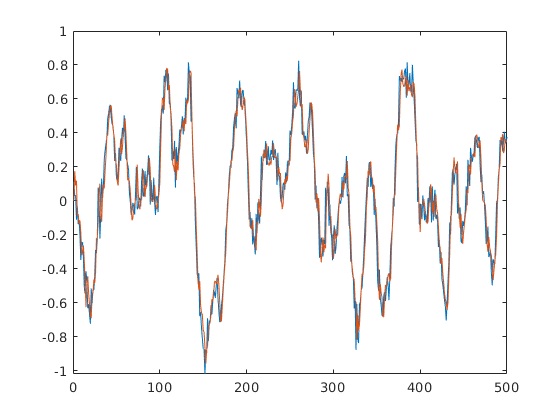

plot(y_2);
hold on;
plot(estimative3x);
hold off;